# A thin rolling wheel(NO slip) **- **Equations of motion via **Newton**

In this tutorial, we're going to use **Newton's 2nd Law** to derive the equations of motion of a **thin wheel(or disk) that rolls along the ground**.  We'll apply a **"NO slip" constraint** that allows us to reduce the general 6-dof system down to a 3-dof system.  The geometry and dimensions of the wheel are shown in Figure 1 below.

**Figure 1:  The thin wheel**

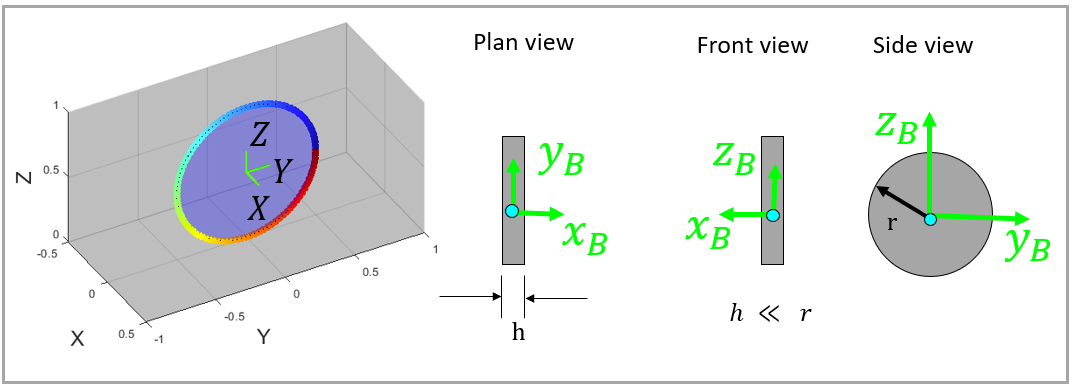

The **Analysis workflow** that we'll adopt is summarised below:

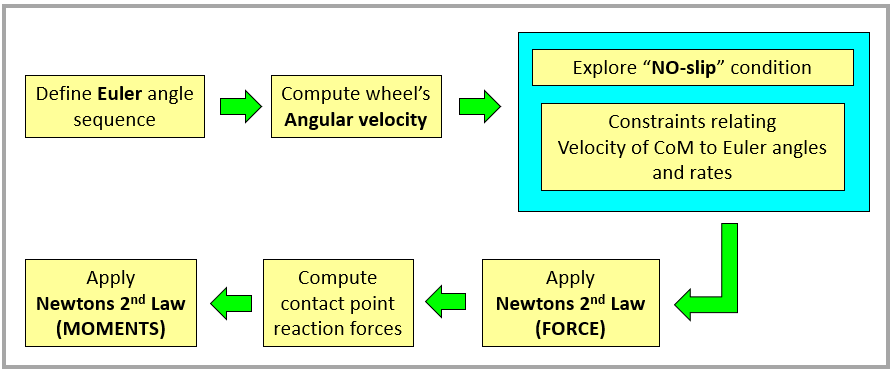

`Bradley Horton : 09-Nov-2020, bhorton@mathworks.com`

## Start with a clean slate

Clear any workspace varables

clc;  clear

## The Angular orientation of the wheel

Let's use 3 **Euler angles **to describe the wheel's angular orientation.  

- $R_{1Z}$ occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- $R_{2Y}$ occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- $R_{3X}$ occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can then express a vector defined in terms of the **Inertial {E-frame}** components , to it's corresponding components in a **body fixed {B-frame}**, using a sequence of **PASSIVE** rotation matrices, ie:

- 
$$v^B \;=\;\;\left\lbrack R_{3X} \left(\psi \right)\right\rbrack \;\ldotp \left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp \;\;v^E \;$$


This Euler angle sequence is illustrated below

     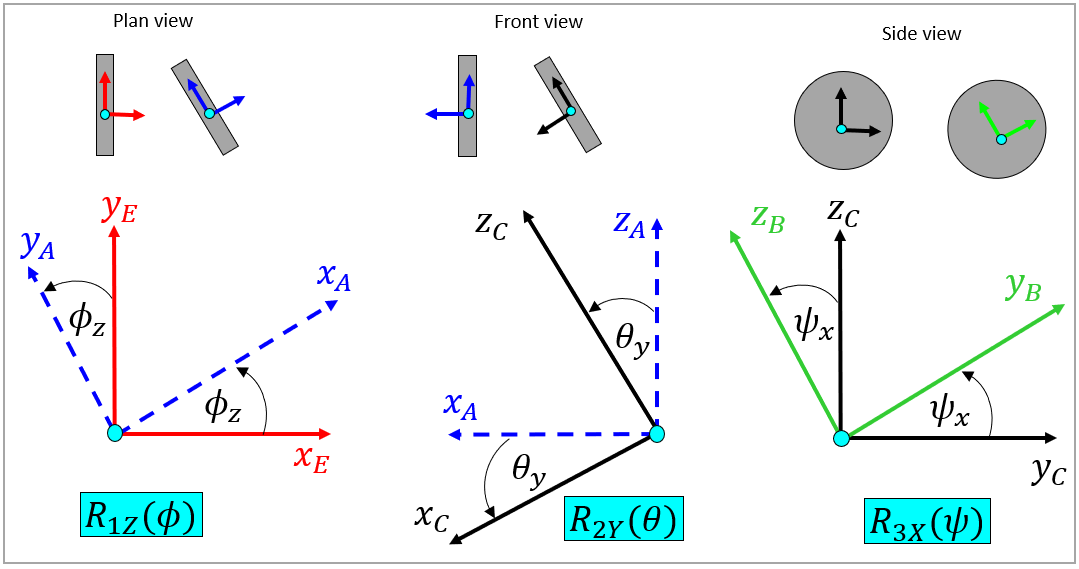   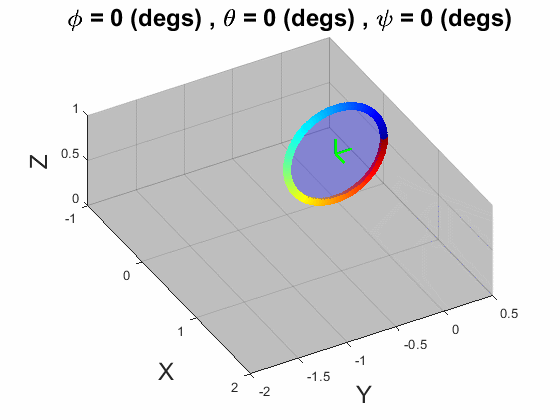

We'll use some symbolic variables to represent these **Euler angles and their rates **as well as some physical properties like mass and gravity

syms  m g r
syms  t 
syms  phi        theta        psi
syms  phi_dot    theta_dot    psi_dot
syms  phi_ddot   theta_ddot   psi_ddot
syms  PHI(t)     THETA(t)     PSI(t)

% vars_pretty = [ phi        theta        psi,  ...
%                 phi_dot    theta_dot    psi_dot, ...
%                 phi_ddot   theta_ddot   psi_ddot ];
% 
% vars_actual = [      PHI(t)            THETA(t)            PSI(t), ...
%                 diff(PHI(t),t,1), diff(THETA(t),t,1), diff(PSI(t),t,1), ...
%                 diff(PHI(t),t,2), diff(THETA(t),t,2), diff(PSI(t),t,2)];


vars_pretty = [ phi_ddot   theta_ddot   psi_ddot, ...
                phi_dot    theta_dot    psi_dot, ...
                phi        theta        psi  ...   
             ];

vars_actual = [ diff(PHI(t),t,2), diff(THETA(t),t,2), diff(PSI(t),t,2), ...
                diff(PHI(t),t,1), diff(THETA(t),t,1), diff(PSI(t),t,1), ...
                          PHI(t),           THETA(t),           PSI(t)                
                ];

Let's breakdown each of these **Euler rotation sequences** and illustrate them below:

## The Angular velocity of the wheel

Corresponding to each frame rotation, are the associated angular velocities.  We can define these angular velocities initially in components of their local frames, 

- $\;\omega_{1Z}^A \;={\left\lbrack \begin{array}{ccc}
0 & 0 & \dot{\phi} 
\end{array}\right\rbrack }^T$    and     $\;\omega_{2Y}^C ={\left\lbrack \begin{array}{ccc}
0 & \dot{\theta}  & 0
\end{array}\right\rbrack }^T$   and     $\omega_{3X}^B ={\left\lbrack \begin{array}{ccc}
\dot{\psi}  & 0 & 0
\end{array}\right\rbrack }^T$

And then we can use PASSIVE rotation matrices to express them in components of the body fixed {B-frame}.  When we sum these angular velocities, we finally get the angular velocity of the wheel

- 
$$\;\omega_{\textrm{WHEEL}}^B =\;\;R_X \left(\psi \right)\ldotp R_Y \left(\theta \right)\ldotp \omega_{1Z}^A \;\;\;\;\;\;+\;\;\;\;\;R_X \left(\psi \right)\ldotp \omega_{2Y}^C \;\;\;\;\;\;+\;\;\;\;\;\;\omega_{3X}^B$$


omega_B_wheel =  LOC_get_RX(psi)*LOC_get_RY(theta)*[0;0;phi_dot] + ...
                 LOC_get_RX(psi)*[0;theta_dot;0]                + ...
                 [psi_dot;0;0]

$$omega\_B\_wheel = \left(\begin{array}{c} \dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\theta }\,\cos\left(\psi \right)+\dot{\varphi }\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \dot{\varphi }\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\dot{\theta }\,\sin\left(\psi \right) \end{array}\right)$$

Having computed the wheel's angular velocity, we can now use PASSIVE rotation matrices to express the angular velocity vector into components of other frames.  A frame of interest is the {C-frame}.  Recall the relationship between the {B-frame} and {C-frame}:

- 
$${\omega_{\textrm{WHEEL}}^B \;=\;R}_X \left(\psi \right)\ldotp \omega_{\textrm{WHEEL}}^C$$
      
$$\Longrightarrow$$
     
$$\;\omega_{\textrm{WHEEL}}^C ={\left\lbrack {\;R}_X \left(\psi \right)\right\rbrack }^{-1} \;\ldotp \omega_{\textrm{WHEEL}}^B \;$$
   

omega_C_wheel = inv(LOC_get_RX(psi)) * omega_B_wheel;
omega_C_wheel = simplify(omega_C_wheel)

$$omega\_C\_wheel = \left(\begin{array}{c} \dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\theta }\\ \dot{\varphi }\,\cos\left(\theta \right) \end{array}\right)$$

## The {C-frame}, aka the "shape frame"

The {C-frame} is significant because it allows us to apply the "no slip" condition.  Recall that the {C-frame} is a "semi fixed" frame (often referred to as a "shape" frame).  It's "semi fixed" because  $v^C \;\;=\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp v^E$.  So the  {C-frame} **only** yaws and pitches with the wheel.   The full "body fixed" {B-frame} rotates relative to the {C-frame} via  $\omega_{3X}^B ={\left\lbrack \begin{array}{ccc}
\dot{\psi}  & 0 & 0
\end{array}\right\rbrack }^T$

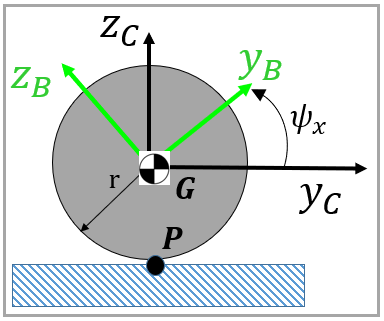

At the point where the wheel touches the ground we can say  $v_P =v_G \;\;+v_{P\left|G\right.}$  .  We can use a combination of frames to help us compute this.  And as usual, when we add 2 vectors together, we need to ensure that their components are in the same frame.  The {C-frame} is a convenient frame to consider ... because the position of the contact point is always $r_P^C \;={\left\lbrack \begin{array}{ccc}
0 & 0 & -r
\end{array}\right\rbrack }^T$  

- 
$$v_P^C \;\;\;=\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;v_G^C \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;\;\;\omega_{\textrm{WHEEL}}^C \times r_P^C \;\;$$
 
$$\;\;\;\;$$


- 
$$v_P^C \;\;=\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp v_G^E \;\;\;\;\;+\;\;\;\omega_{\textrm{WHEEL}}^C \times r_P^C$$


So first define the velocity of $G$ in components of the inertial {E-frame}:    $v_G^E$

syms X_dot_G__E   Y_dot_G__E   Z_dot_G__E  

v_G__E = [ X_dot_G__E;   
           Y_dot_G__E;
           Z_dot_G__E  ];

And then convert this $v_G^E$ {E-frame} vector into it's corresponding components in the {C-frame}:   $v_G^C \;=\;\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp v_G^E$

v_G__C = LOC_get_RY(theta) * LOC_get_RZ(phi) * v_G__E

$$v\_G\_\_C = \left(\begin{array}{c} {\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-{\dot{Z}}_{G}^{E}\,\sin\left(\theta \right)+{\dot{Y}}_{G}^{E}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ {\dot{Y}}_{G}^{E}\,\cos\left(\varphi \right)-{\dot{X}}_{G}^{E}\,\sin\left(\varphi \right)\\ {\dot{Z}}_{G}^{E}\,\cos\left(\theta \right)+{\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+{\dot{Y}}_{G}^{E}\,\sin\left(\varphi \right)\,\sin\left(\theta \right) \end{array}\right)$$

And finally, compute the total velocity of point $P$

v_P__C = v_G__C  +  cross(omega_C_wheel, [0;0;-r])

$$v\_P\_\_C = \left(\begin{array}{c} {\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-{\dot{Z}}_{G}^{E}\,\sin\left(\theta \right)-r\,\dot{\theta }+{\dot{Y}}_{G}^{E}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ r\,\left(\dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\right)+{\dot{Y}}_{G}^{E}\,\cos\left(\varphi \right)-{\dot{X}}_{G}^{E}\,\sin\left(\varphi \right)\\ {\dot{Z}}_{G}^{E}\,\cos\left(\theta \right)+{\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+{\dot{Y}}_{G}^{E}\,\sin\left(\varphi \right)\,\sin\left(\theta \right) \end{array}\right)$$

## Enforcing the NON-slip condition

For the NON-slip condition, we require that $0=\;v_P^C$  , ie:

- 
$$v_{\textrm{XP}}^C =0\;\;\;\;\Longrightarrow \;$$

$$\textrm{NO}\;\textrm{sliding}$$


- 
$$v_{\textrm{YP}}^C =0\;\;\;\;\Longrightarrow \;\textrm{NO}\;\textrm{sliding}$$


- $v_{\textrm{ZP}}^C =0\;\;\;\;\Longrightarrow \;$Point $P$ stays in contact with the ground

tmp_EQ = 0 == v_P__C;

Enforcing the NON-slip condition then allows us to extract the constraints relating the velocity of the center of mass to the Euler angles and rates

tmp_sol    = solve(tmp_EQ, [X_dot_G__E;   Y_dot_G__E;   Z_dot_G__E]);
 
X_dot_G__E = simplify(tmp_sol.X_dot_G__E);
Y_dot_G__E = simplify(tmp_sol.Y_dot_G__E);
Z_dot_G__E = simplify(tmp_sol.Z_dot_G__E);

We now can use Euler angles and rates to express the velocity of the center of mass $G$ of the wheel in components of the inertial {E-frame} 

-    
$$\;v_G^E \;\;={\left\lbrack \begin{array}{ccc}
{\dot{X} }_G^E  & {\dot{Y} }_G^E  & {\dot{Z} }_G^E 
\end{array}\right\rbrack }^T \;\;=\;\;f\left(\phi ,\theta ,\psi ,\dot{\phi} ,\dot{\theta} ,\dot{\psi} \right)\;$$


v_G__E = [   X_dot_G__E;
             Y_dot_G__E;
             Z_dot_G__E; ]

$$v\_G\_\_E = \left(\begin{array}{c} r\,\left(\dot{\psi }\,\sin\left(\varphi \right)+\dot{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\dot{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)\\ r\,\left(\dot{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)-\dot{\psi }\,\cos\left(\varphi \right)+\dot{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)\\ -r\,\dot{\theta }\,\sin\left(\theta \right) \end{array}\right)$$

 **SUNLIGHT test: ** We can write the velocity of point $P$ in components of the inertial {E-frame} ...we're expecting it to be ZERO !

- 
$$v_P^E =\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;v_G^E \;\;\;\;\;+\;\;\;\;\;\;{\left(\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \right)}^{-1} \;\;\ldotp \left(\omega_{\textrm{WHEEL}}^C \times r_P^C \right)\;\;\;\;$$
 

tmp_zero = v_G__E  + inv(LOC_get_RY(theta) * LOC_get_RZ(phi)) * cross(omega_C_wheel, [0;0;(-r)]);
tmp_zero = simplify(tmp_zero)

$$tmp\_zero = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Good !

## **Now let's compute the acceleration of the center of mass:**

Since $v_G^E$ is expressed in terms of the inertial {E-frame}, we can compute the acceleration of the center of mass by direct differentiation, ie:

- 
$$a_G^E \;\;=\;\;\frac{\mathrm{d}}{\mathrm{d}t}\left(v_G^E \right)$$


tmp_v  = subs(v_G__E, vars_pretty, vars_actual);
a_G__E = diff(tmp_v, t);
a_G__E = subs(a_G__E, vars_actual, vars_pretty);

a_G__E = simplify(a_G__E)

$$a\_G\_\_E = \left(\begin{array}{c} -r\,\left(\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\dot{\varphi }\,\dot{\theta }-\dot{\psi }\,\cos\left(\varphi \right)\,\dot{\varphi }+\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\ddot{\psi }\,\sin\left(\varphi \right)-\ddot{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)+\ddot{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)\\ r\,\left(-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\dot{\varphi }\,\dot{\theta }+\dot{\psi }\,\sin\left(\varphi \right)\,\dot{\varphi }-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\ddot{\psi }\,\cos\left(\varphi \right)+\ddot{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+\ddot{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)\\ -r\,\left(\cos\left(\theta \right)\,{\dot{\theta }}^{2}+\ddot{\theta }\,\sin\left(\theta \right)\right) \end{array}\right)$$

We're now in a really good position to apply Newton's 2nd law.

## Newton's 2nd Law:   The Force balance

What makes this problem interesting, is that as the wheel rolls along the ground, the point of contact with the ground changes relative to the body fixed {B-frame}.  For example, consider 3 values for the roll angle $\psi \;$shown below:

- The wheel rotates about the body fixed $X-\textrm{axis}$  (pointing out of the page)

- The $\psi \;$rotation causes the wheel to move to the left

- NOTE: how the contact point $P$ is constantly changing  (eg:  orange ..... green  ..... light blue)

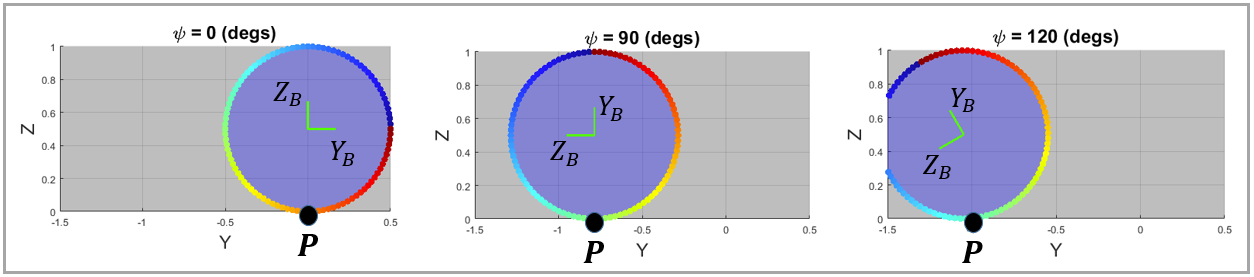

However, from the {C-frame} the point of contact $P$ is always at the position $r_P^C \;={\left\lbrack \begin{array}{ccc}
0 & 0 & -r
\end{array}\right\rbrack }^T$, as shown below.  This is another reason that makes the {C-frame} so useful and we 'll use this feature when we apply Newton's laws.

Newton's 2nd law expressed in terms of the INERTIAL {E-frame} is:   $\;F^E =m\ldotp a_G^E$ . Let's focus on the LHS first. The free body diagram for the wheel is shown below.  We have the gravity force, and the reaction forces $F_{P\;\textrm{reaction}}^C$ acting at the ground contact point $P$.  We have drawn the reaction forces at point $P$ in the {C-frame}.

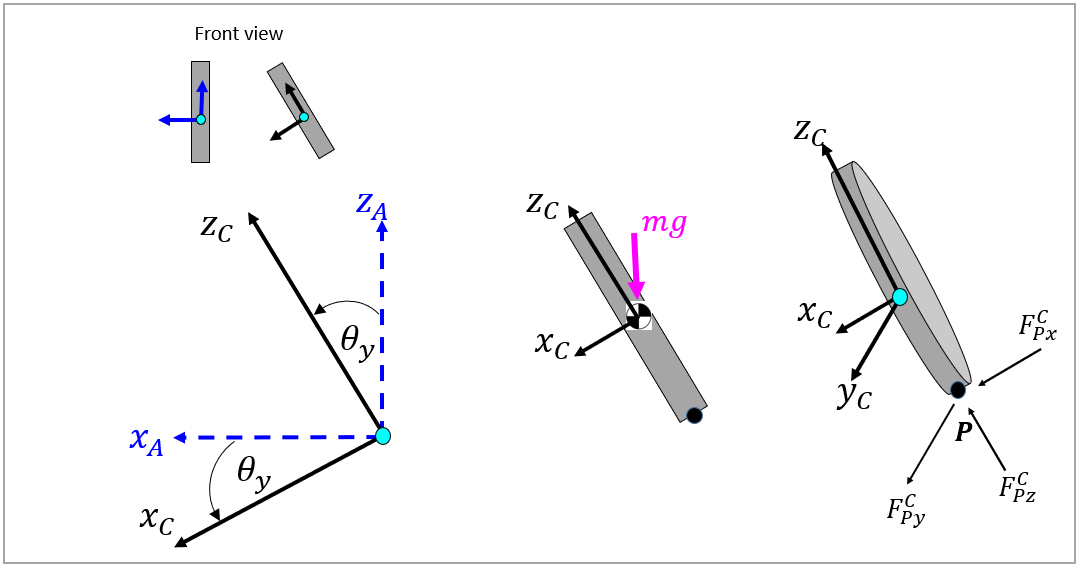

So the NET force acting on the wheel, expressed in components of the {C-frame} is

- 
$$F^C =\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp F_{\textrm{Gravity}}^E \;\;\;\;\;\;+\;\;\;\;F_{P\;\textrm{reaction}}^C$$


syms F_xp__C  F_yp__C  F_zp__C    

F_C = LOC_get_RY(theta) * LOC_get_RZ(phi) * [0;0;(-m*g)]  +  [F_xp__C;  F_yp__C;  F_zp__C];

And we can convert this net force vector into it's components in the {E-frame}

$F^C \;\;=\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp F^E$   therefore   $F^E \;\;={\left(\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \right)}^{-1} \;\ldotp F^C$

F_E = inv( LOC_get_RY(theta) * LOC_get_RZ(phi))* F_C;  
F_E = simplify(F_E)

$$F\_E = \left(\begin{array}{c} F_{\mathrm{xp}}^{C}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-F_{\mathrm{yp}}^{C}\,\sin\left(\varphi \right)+F_{\mathrm{zp}}^{C}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ F_{\mathrm{yp}}^{C}\,\cos\left(\varphi \right)+F_{\mathrm{xp}}^{C}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)+F_{\mathrm{zp}}^{C}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ F_{\mathrm{zp}}^{C}\,\cos\left(\theta \right)-g\,m-F_{\mathrm{xp}}^{C}\,\sin\left(\theta \right) \end{array}\right)$$

So assembling Newton's 2nd Law $\;F^E =m\ldotp a_G^E$  now gives us:

my_F_EQ =   F_E == m * a_G__E

$$my\_F\_EQ = \left(\begin{array}{c} F_{\mathrm{xp}}^{C}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-F_{\mathrm{yp}}^{C}\,\sin\left(\varphi \right)+F_{\mathrm{zp}}^{C}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)=-m\,r\,\left(\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\dot{\varphi }\,\dot{\theta }-\dot{\psi }\,\cos\left(\varphi \right)\,\dot{\varphi }+\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\ddot{\psi }\,\sin\left(\varphi \right)-\ddot{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)+\ddot{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)\\ F_{\mathrm{yp}}^{C}\,\cos\left(\varphi \right)+F_{\mathrm{xp}}^{C}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)+F_{\mathrm{zp}}^{C}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)=m\,r\,\left(-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\dot{\varphi }\,\dot{\theta }+\dot{\psi }\,\sin\left(\varphi \right)\,\dot{\varphi }-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\ddot{\psi }\,\cos\left(\varphi \right)+\ddot{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+\ddot{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)\\ F_{\mathrm{zp}}^{C}\,\cos\left(\theta \right)-g\,m-F_{\mathrm{xp}}^{C}\,\sin\left(\theta \right)=-m\,r\,\left(\cos\left(\theta \right)\,{\dot{\theta }}^{2}+\ddot{\theta }\,\sin\left(\theta \right)\right) \end{array}\right)$$

Which we can use to solve for the reaction forces $F_{P\;\textrm{reaction}}^C$ at the contact point

tmp_sol = solve(my_F_EQ, [F_xp__C;  F_yp__C;  F_zp__C]);

my_FC_react_col = [ simplify(tmp_sol.F_xp__C);
                    simplify(tmp_sol.F_yp__C);
                    simplify(tmp_sol.F_zp__C); ]

$$my\_FC\_react\_col = \left(\begin{array}{c} m\,\left(-r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+\dot{\psi }\,r\,\cos\left(\theta \right)\,\dot{\varphi }+r\,\ddot{\theta }-g\,\sin\left(\theta \right)\right)\\ m\,r\,\left(\ddot{\varphi }\,\sin\left(\theta \right)-\ddot{\psi }+2\,\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\right)\\ m\,\left(r\,{\dot{\varphi }}^{2}\,{\cos\left(\theta \right)}^{2}-r\,{\dot{\varphi }}^{2}+\dot{\psi }\,r\,\sin\left(\theta \right)\,\dot{\varphi }-r\,{\dot{\theta }}^{2}+g\,\cos\left(\theta \right)\right) \end{array}\right)$$

The moment of these reaction forces about the centre of mass is

- 
$$M_G^C \;\;\;\;\;=\;\;r_P^C \;\;\times \;\;F_{P\;\textrm{reaction}}^C \;$$


my_MC = cross([0;0;(-r)], my_FC_react_col  )

$$my\_MC = \left(\begin{array}{c} m\,r^{2}\,\left(\ddot{\varphi }\,\sin\left(\theta \right)-\ddot{\psi }+2\,\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\right)\\ -m\,r\,\left(-r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+\dot{\psi }\,r\,\cos\left(\theta \right)\,\dot{\varphi }+r\,\ddot{\theta }-g\,\sin\left(\theta \right)\right)\\ 0 \end{array}\right)$$

We'll use the above result next when we consider the Moment version of Newton's 2nd law.

## Newton's 2nd Law:   The Moment balance

Consider the following definitions:

- $\omega_{\textrm{wheel}}^C$   - is the total **angular velocity of the wheel** expressed in components of the {C-frame}

- $\omega_{\textrm{frame}}^C$   - is the **angular velocity of the {C-frame}** expressed in components of the {C-frame}

- $M_G^C \;$     - the total moment about the center of mass $G$ expressed in components of the {C-frame}

- $H_G^C$      - the Angular momentum of the wheel about it's center of mass $G$ and expressed in components of the {C-frame}.

- $I_G$        - the wheel is axisymmetric, therefore the inertia matrix about the {B-frame} is identical to that about the {C-frame}

Newton's 2nd Law states   $M_G \;=\;\;\frac{\mathrm{d}}{\mathrm{d}t}H_G$ .  When the vectors are expressed in components of a frame that rotates, we need to apply the transport theorem, ie:

- 
$$M_G^C \;={\left(\frac{d}{\mathrm{d}t}H_G^C \right)}_{\textrm{local}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;\;\;\omega_{\textrm{frame}}^C \;\times \left(H_G^C \right)\;\;\;$$
  

-  
$$M_G^C \;\;=\;\;\;\;I_G \ldotp {\left\lbrace {\dot{\omega} }_{\textrm{wheel}}^C \right\rbrace }_{\textrm{local}} \;\;\;\;+\;\;\;\;\;\;\omega_{\textrm{frame}}^C \;\times \left(I_G \ldotp \omega_{\textrm{wheel}}^C \right)$$


First define $\omega_{\textrm{frame}}^C$:

omega_C_frame =  LOC_get_RY(theta)*[0;0;phi_dot] + [0;theta_dot;0];

Next define the Inertia matrix - the wheel is axisymetric where  $I_{\textrm{YY}} =I_{\textrm{ZZ}}$

syms  I_xx  I_yy

I_mat   = [  I_xx,      0,      0;
                0,   I_yy,      0;
                0,      0,   I_yy   ];

Now compute the "local" derivative of  $\omega_{\textrm{wheel}}^C$

tmp_w  = subs(omega_C_wheel, vars_pretty, vars_actual);
wdot_C = diff(tmp_w, t);
wdot_C = subs(wdot_C, vars_actual, vars_pretty);
wdot_C = simplify(wdot_C)

$$wdot\_C = \left(\begin{array}{c} \ddot{\psi }-\ddot{\varphi }\,\sin\left(\theta \right)-\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\\ \ddot{\theta }\\ \ddot{\varphi }\,\cos\left(\theta \right)-\dot{\varphi }\,\dot{\theta }\,\sin\left(\theta \right) \end{array}\right)$$

Finally, assemble Newton's equation:   $M_G^C \;\;=\;\;\;\;I_G \ldotp {\left\lbrace {\dot{\omega} }_{\textrm{wheel}}^C \right\rbrace }_{\textrm{local}} \;\;\;\;+\;\;\;\;\omega_{\textrm{frame}}^C \;\times \left(I_G \ldotp \omega_{\textrm{wheel}}^C \right)$

EQ_M = my_MC == I_mat*wdot_C  + cross(omega_C_frame,  I_mat*omega_C_wheel);
EQ_M = simplify(EQ_M) 

$$EQ\_M = \left(\begin{array}{c} m\,r^{2}\,\left(\ddot{\varphi }\,\sin\left(\theta \right)-\ddot{\psi }+2\,\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\right)=-I_{\mathrm{xx}}\,\left(\ddot{\varphi }\,\sin\left(\theta \right)-\ddot{\psi }+\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\right)\\ -m\,r\,\left(-r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+\dot{\psi }\,r\,\cos\left(\theta \right)\,\dot{\varphi }+r\,\ddot{\theta }-g\,\sin\left(\theta \right)\right)=I_{\mathrm{yy}}\,\ddot{\theta }+I_{\mathrm{yy}}\,{\dot{\varphi }}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)+I_{\mathrm{xx}}\,\dot{\varphi }\,\cos\left(\theta \right)\,\left(\dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\right)\\ I_{\mathrm{yy}}\,\left(\ddot{\varphi }\,\cos\left(\theta \right)-\dot{\varphi }\,\dot{\theta }\,\sin\left(\theta \right)\right)=I_{\mathrm{xx}}\,\dot{\theta }\,\left(\dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\right)+I_{\mathrm{yy}}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(\theta \right) \end{array}\right)$$

And now we can convert this result into a nice $A\ldotp x=b$ form, where $x={\left\lbrack \ddot{\phi} \;\;,\;\ddot{\theta} \;\;,\;\ddot{\psi} \right\rbrack }^T$

[my_sol_A_mat, my_sol_b_mat] = equationsToMatrix(EQ_M, [phi_ddot, theta_ddot, psi_ddot] );

And we can solve for the Euler accelerations:

- 
$${\left\lbrack \ddot{\phi} \;\;,\;\ddot{\theta} \;\;,\;\ddot{\psi} \right\rbrack }^T$$


Newt_acc_col = simplify(  my_sol_A_mat \  my_sol_b_mat  )

$$Newt\_acc\_col = \left(\begin{array}{c} \frac{\dot{\theta }\,\left(I_{\mathrm{xx}}\,\dot{\psi }-I_{\mathrm{xx}}\,\dot{\varphi }\,\sin\left(\theta \right)+2\,I_{\mathrm{yy}}\,\dot{\varphi }\,\sin\left(\theta \right)\right)}{I_{\mathrm{yy}}\,\cos\left(\theta \right)}\\ \frac{\frac{I_{\mathrm{xx}}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}-\frac{I_{\mathrm{yy}}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}-I_{\mathrm{xx}}\,\dot{\varphi }\,\dot{\psi }\,\cos\left(\theta \right)+g\,m\,r\,\sin\left(\theta \right)+\frac{m\,{\dot{\varphi }}^{2}\,r^{2}\,\sin\left(2\,\theta \right)}{2}-m\,\dot{\varphi }\,\dot{\psi }\,r^{2}\,\cos\left(\theta \right)}{m\,r^{2}+I_{\mathrm{yy}}}\\ \frac{\dot{\theta }\,\left(-\dot{\varphi }\,{I_{\mathrm{xx}}}^{2}\,{\sin\left(\theta \right)}^{2}+\dot{\psi }\,{I_{\mathrm{xx}}}^{2}\,\sin\left(\theta \right)-m\,\dot{\varphi }\,I_{\mathrm{xx}}\,r^{2}\,{\sin\left(\theta \right)}^{2}+m\,\dot{\psi }\,I_{\mathrm{xx}}\,r^{2}\,\sin\left(\theta \right)+I_{\mathrm{yy}}\,\dot{\varphi }\,I_{\mathrm{xx}}\,{\sin\left(\theta \right)}^{2}+I_{\mathrm{yy}}\,\dot{\varphi }\,I_{\mathrm{xx}}+2\,I_{\mathrm{yy}}\,m\,\dot{\varphi }\,r^{2}\right)}{I_{\mathrm{yy}}\,\cos\left(\theta \right)\,\left(m\,r^{2}+I_{\mathrm{xx}}\right)} \end{array}\right)$$

Having derived the equations of motion, eventually we'll want to solve them.  For some systems an analytic solution may be possible, but often an analytic solution is not possible (think large dofs with arbitrary excitation forces and torques).  So in general, numerical techniques are used to solve systems of ordinary differential equations.  To use numeric solvers we need to "present" our equations in a certain way.  Today we'll be using Simulink to numerically solve our equations ... and the format that Simulink requires is summarised below:

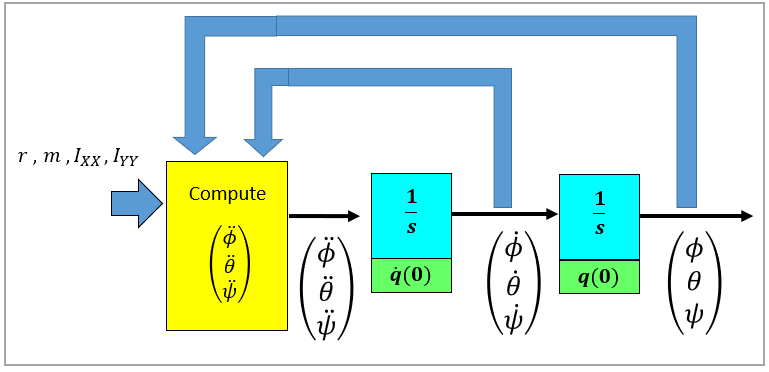

##  Create a Simulink block of our equations

In the next tutorial, we're going to simulate the dynamics that we've just derived, i.e. we'll specify numeric values for our wheel parameters (e.g.:  $r,m,I_{\textrm{XX}} ,I_{\textrm{YY}}$  etc) and we'll numerically solve the non linear ODEs derived above.  Although we could perform this simulation in MATLAB, there is another (even easier) way - it's called Simulink.  But in order to use Simulink we need a way of importing our derived equations of motion.  Rather than writing out by hand the derived equations, we'll use the [`matlabFunctionBlock()`](matlab:  web(fullfile(docroot, 'symbolic/matlabfunctionblock.html'))) function to automatically convert these equations into a MATLAB Function block.  Conceptually we're going to perform the task shown below:

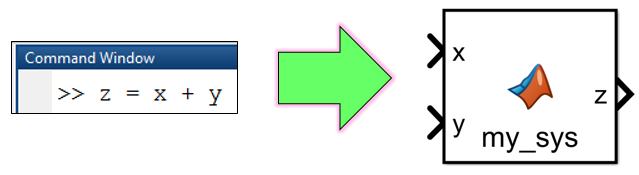     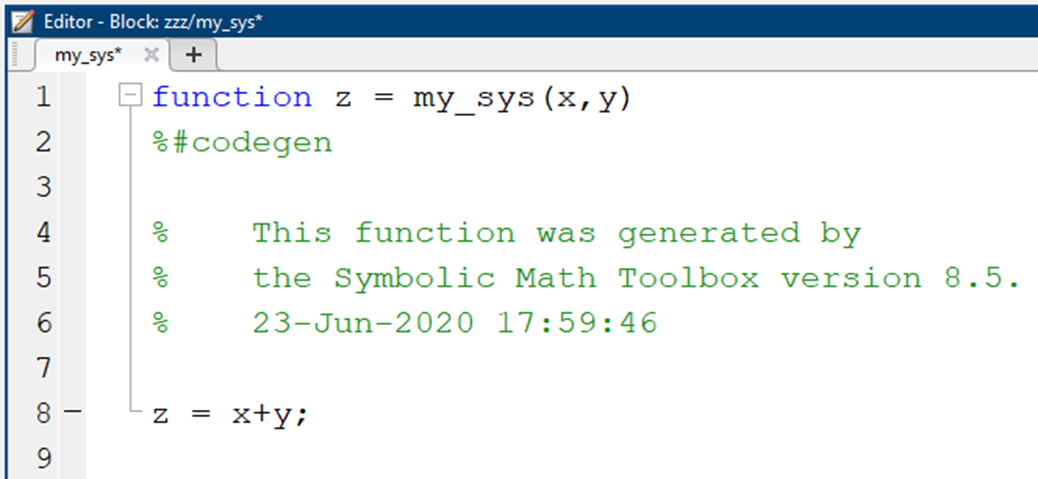

tf_i_should_create_SL_block = true;

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_Ab_NEWT_rolling';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_A_and_b_Newton'], ...
                         my_sol_A_mat,    my_sol_b_mat,  ...
                        'Outputs',  {'A', 'b'},  ...
                        'Optimize', false );
                    
    % make the block a YELLOW color
    set_param([MODEL_NAME,'/my_A_and_b_Newton'],'BackgroundColor','[1, 1, 0.607843]')

    %-------------------------------------------------------
    % Create a block that computes the CONTACT forces 
    % at point P expressed in the inertial E frame
    my_FE_react_col = inv( LOC_get_RY(theta) * LOC_get_RZ(phi))* my_FC_react_col;  
    my_FE_react_col = simplify(my_FE_react_col)

    matlabFunctionBlock( [MODEL_NAME,'/my_FE_P_force'], ...
                         my_FE_react_col,  ...
                        'Outputs',  {'FE_P'},  ...
                        'Optimize', false );
                    
    % make the block a CYAN color
    set_param([MODEL_NAME,'/my_FE_P_force'],'BackgroundColor','[0,1,1]')
end

$$my\_FE\_react\_col = \left(\begin{array}{c} -m\,r\,\left(\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\dot{\varphi }\,\dot{\theta }-\dot{\psi }\,\cos\left(\varphi \right)\,\dot{\varphi }+\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\ddot{\psi }\,\sin\left(\varphi \right)-\ddot{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)+\ddot{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)\\ m\,r\,\left(-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\dot{\varphi }\,\dot{\theta }+\dot{\psi }\,\sin\left(\varphi \right)\,\dot{\varphi }-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\ddot{\psi }\,\cos\left(\varphi \right)+\ddot{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+\ddot{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)\\ -m\,\left(r\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}-g+r\,\ddot{\theta }\,\sin\left(\theta \right)\right) \end{array}\right)$$

# **Next Steps**

An alternate way of deriving the equations of motion for this system, is to apply the Lagrangian approach - and we'll demonstrate this Lagrangian technique in the script file:

- [`bh_DEMO_02_rolling_wheel_Lagrangian`](matlab: edit bh_DEMO_02_rolling_wheel_Lagrangian)

After applying the Lagrangian technique we'll compare the results of this Newtonian derivation against the Lagrangian derivation.  The comparison will be done running the Simulink model launched by the script file:

- [`bh_DEMO_03_rolling_wheel_Simulation`](matlab:  edit bh_DEMO_03_rolling_wheel_Simulation)

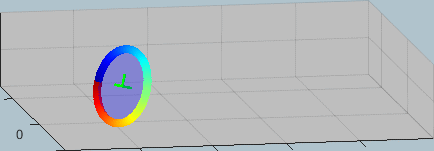

# Local Subfunctions only beyond this point

Hello 

Define the passive Rotation matrix - $R_X \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_X \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RX(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1X'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Y \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Y \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RY(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Y'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Z \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Z \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RZ(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Z'}, a, 'SYM');
    R   = OBJ.get_R;
end

Implement the LHS of Lagranges equation for a single generalise co-ordinate, i.e. compute the following:

- 
$$\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;$$


function EOM_LHS = LOC_do_LHS_lag_eqn(L_ORIGINAL, actual_list, pretty_list, q, q_dot)
    syms t

    L                 = subs(L_ORIGINAL,  actual_list, pretty_list);
    dLdqdot           = diff(L,       q_dot);
    dLdqdot           = subs(dLdqdot,  pretty_list, actual_list);    
    der_dt_of_dLdqdot = diff(dLdqdot, t);
    dLdq              = diff(L, q);
    dLdq              = subs(dLdq,    pretty_list, actual_list);
    
    EOM_LHS           = der_dt_of_dLdqdot - dLdq;
    EOM_LHS           = simplify( EOM_LHS );
end